figure1

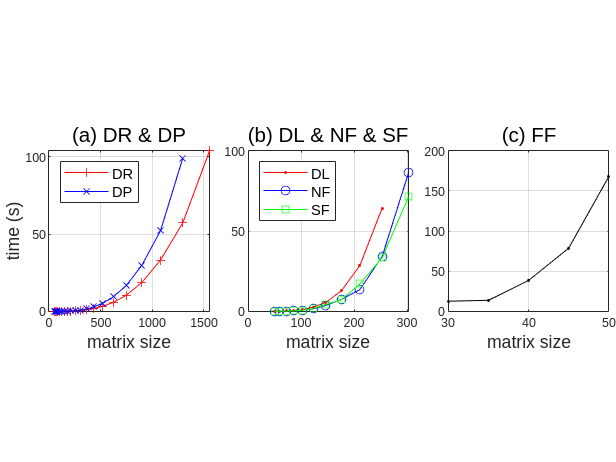

xDR = [50 60 72 86 103 123 147 176 211 253 303 363 435 522 626 751 901 1081 1297 1556];
yDR = [0.01 0 0.01 0.01 0.02 0.04 0.06 0.1 0.17 0.29 0.5 0.91 1.75 3.3 5.81 10.5 18.73 33.17 57.3 103.94];
xDP = [50 60 72 86 103 123 147 176 211 253 303 363 435 522 626 751 901 1081 1297];
yDP = [0.01 0.01 0.01 0.02 0.03 0.05 0.09 0.15 0.26 0.46 0.81 1.5 2.84 5.21 9.51 16.86 29.88 52.21 99.16];
xDL = [50 60 72 86 103 123 147 176 211 253];
yDL = [0.07 0.12 0.26 0.52 1.06 2.62 5.63 12.77 28.51 64.28];
xNF = [50 60 72 86 103 123 147 176 211 253 303];
yNF = [0.04 0.08 0.17 0.36 0.74 1.54 3.73 7.41 13.54 34.16 86.4];
xSF = [50 60 72 86 103 123 147 176 211 253 303];
ySF = [0.04 0.08 0.17 0.35 0.74 1.74 4.28 7.19 17.05 33.34 71.39];
xFF = [30 35 40 45 50];
yFF = [12.54 13.70 38.38 78.69 167.92];

t=tiledlayout(1,3);
t.TileSpacing='compact';
t.Padding='tight';

% (1,2): DR vs DP
t1=nexttile;
plot(xDR,yDR,'r+-', xDP,yDP,'bx-');
grid('on')
legend({'DR','DP'}, 'fontsize', 10, 'Location','northwest');
title('(a) DR & DP', 'fontsize', 14);
xlabel('matrix size', 'fontsize', 12);
ylabel('time (s)', 'fontsize', 12);
pbaspect([1 1 1]) % Control relative lengths of each axis

% (1,3): DL vs NF vs SF
t2=nexttile;
plot(xDL,yDL,'r.-', xNF,yNF,'bo-', xSF, ySF, 'gs-');
grid('on')
% str = {'DL', 'NF'};
legend({'DL', 'NF', 'SF'}, 'fontsize', 10, 'Location','northwest');
title('(b) DL & NF & SF', 'fontsize', 14);
xlabel('matrix size', 'fontsize', 12);
% ylabel('time (s)', 'fontsize', 10);
pbaspect([1 1 1]) % Control relative lengths of each axis

% (1,1): FF
t3=nexttile;
plot(xFF,yFF,'k.-')
grid('on')
title('(c) FF', 'fontsize', 14);
xlabel('matrix size', 'fontsize', 12);
% ylabel('time (s)', 'fontsize', 12);
pbaspect([1 1 1]) % Control relative lengths of each axis

% output （有多余的白色边框，还是手动从matlab的figure中提取 eps 文件）
% fig = gcf;
% fig.PaperPositionMode = 'auto';
% fig_pos = fig.PaperPosition;
% fig.PaperSize = [fig_pos(3) fig_pos(4)];
% print('-painters','-dpdf','-r600','test')